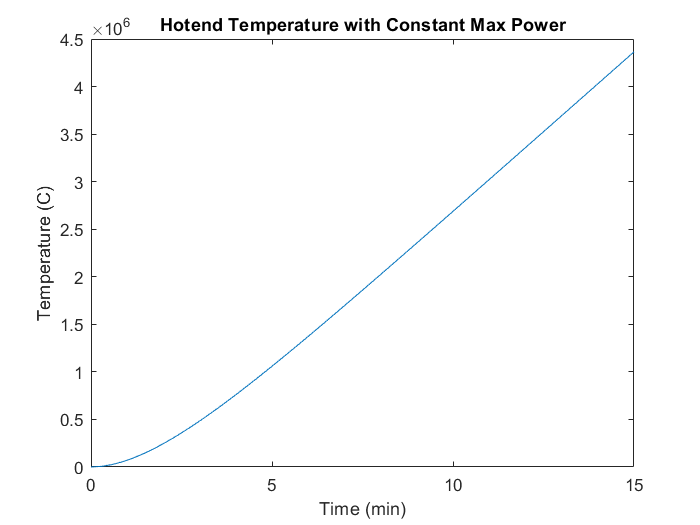

clear
clf 

% Constant Parameters
k_s = 0.3; % W/(m*K), thermal conductivity of silicone (estimate)
L_s = .0015; % m, silicone thickness
% TODO: find approximate h
h_s = 40; % W/(m^2*K), heat transfer coefficient of silicone
A_s =.00173104; % m^2, external surface area of silicone
A_sb =.00118045; % m^2, contact area of block and silicone
c_b = 389; % J/(kg*K), specific heat of block
m_b =.03023; % kg, mass of block (including nozzle)
m_s = .00255; % kg, mass of silicone  
T_air = 296.25; % K, ambient air temperature
T_r = 200; % K, goal temperature
Q_in = 0; % W, input power from heating cartridge #TODO update desc

% User parameters
T_request = 210; % C, requested temperature of the hotend
% PID parameters
Kp = 23.713;
Ki = 1.34; 
Kd = 104.932;


R_total = L_s / (k_s * A_sb) + 1 / (h_s * A_s);

% dTdt = @(t, T_c) 1/c_b * ((T_air - T_c)/R_total + Q_in);
% dTdt = @(T_c) 1/c_b * ((T_c - T_r)/R_total + P*(T_r - T_c) + D(dT/dt) + f) % PID eqn.

tspan = [0 15*3600];
T_initial = 296.15;

% options = odeset("OutputFcn",@heater_power,"OutputSel",[1]); % #TODO update passed components of soln
[t,T] = ode45(@blockTemp, tspan, T_initial, [], Q_in, c_b, T_air, R_total);

plot(t/3600,T-273.15) % convert time to minutes, K to C

xlabel("Time (min)")
ylabel("Temperature (C)")
title("Hotend Temperature with Constant Max Power")

function dTdt = blockTemp(t, T, Q_in, c_b, T_air, R_total)
    Q_in = 5 * t;    
    dTdt = 1/c_b * ((T_air - T)/R_total + Q_in);
end

% function status = heater_power(t,T,flag)
%     assignin("base","Q_in",40)
%     status = false;
% end